# Ising横场精确对角化

[多体物理python入门——Ising模型和稀疏矩阵 - 知乎](https://zhuanlan.zhihu.com/p/114867281)


$$H=-J\sum_{i=1}^L\sigma^x_i\sigma^x_{i+1}-h\sum_{i=1}^L\sigma_i^z$$


sx = sparse([0, 1; 1, 0]);
sy = sparse([0,-1i; 1i,0]);
sz = sparse([1, 0; 0, -1]);

sxsx = kron(sx, sx);
L = 10;  J = 1.0;
h = 0:0.01:2;
Num_Spectrum = 100;
Spectrum = zeros(length(h), Num_Spectrum);

for jj = 1:length(h) 
    H = -kron(kron(sx, speye(2 ^ (L - 2))), sx);
    for ii = 1: L-1
        H = H - kron(speye(2^(ii - 1)), kron(J * sxsx, speye(2^(L - 1 - ii))));
    end
    for ii = 1:L
        H = H - kron(speye(2^(ii-1)), kron(h(jj) * sz, speye(2^(L-ii))));
    end
    Spectrum(jj, :) = eigs(H, Num_Spectrum, 'sa');
    Spectrum(jj, :) = Spectrum(jj, :) - Spectrum(jj, 1);
end

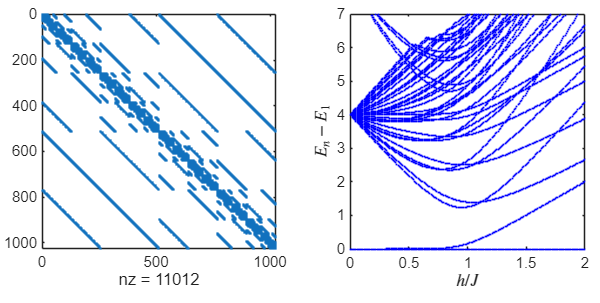

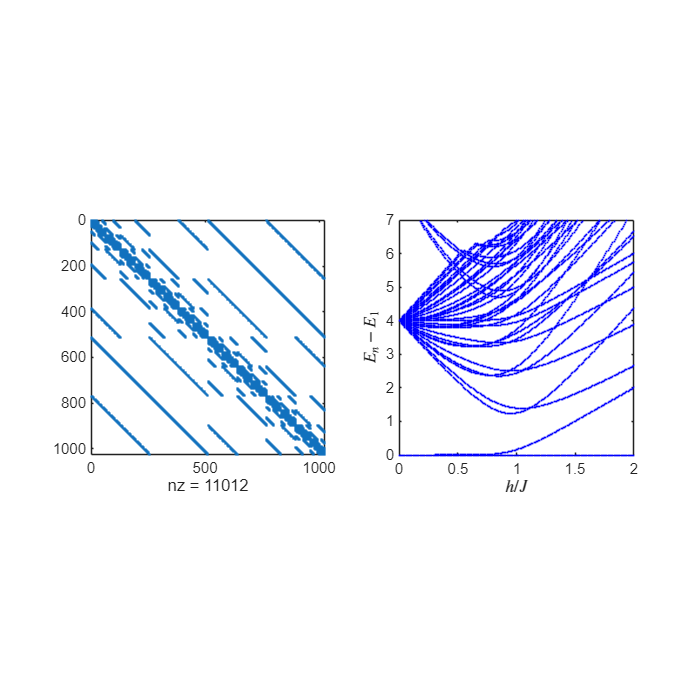

figure(1)
subplot(1,2,1)
spy(H);
set(gca,'LineWidth',1);
subplot(1,2,2)
plot(h', Spectrum, '.','Color','b','MarkerSize',2)
xlabel('$h/J$','Interpreter','latex')
ylabel('$E_n-E_1$','Interpreter','latex')
axis square
set(gca,'LineWidth',1);
ylim([0,7])